# **Creating a Flight Tracking Dashboard, Part 1: Visualizing an Aircraft**

**Overview**

MATLAB provides a large suite of visualization functions tailored to scientific and engineering applications. In addition, MATLAB enables you to develop domain-specific visualizations. These can be embedded in all data analytics workflows, ranging from small-scale interactive [tasks](https://www.mathworks.com/help/releases/R2023b/matlab/develop-live-editor-tasks.html) to more complex [reports](https://www.mathworks.com/products/matlab-report-generator.html), [apps](https://www.mathworks.com/products/matlab/app-designer.html) and [web apps](https://www.mathworks.com/products/matlab-web-app-server.html) such as dashboard-like front ends.

Let's assume that we've been tasked with developing a custom dashboard for monitoring an aircraft during a flight. Over the course of this three-part blog series, we'll see how to put together this dashboard by breaking it down into several simpler steps.

Here's a rough sketch of what we'll be laying out. We'll be including visualizations for tracking the aircraft during its flight, and flight instruments to display the flight data. There will also be some controls for configuring the appearance of the dashboard.

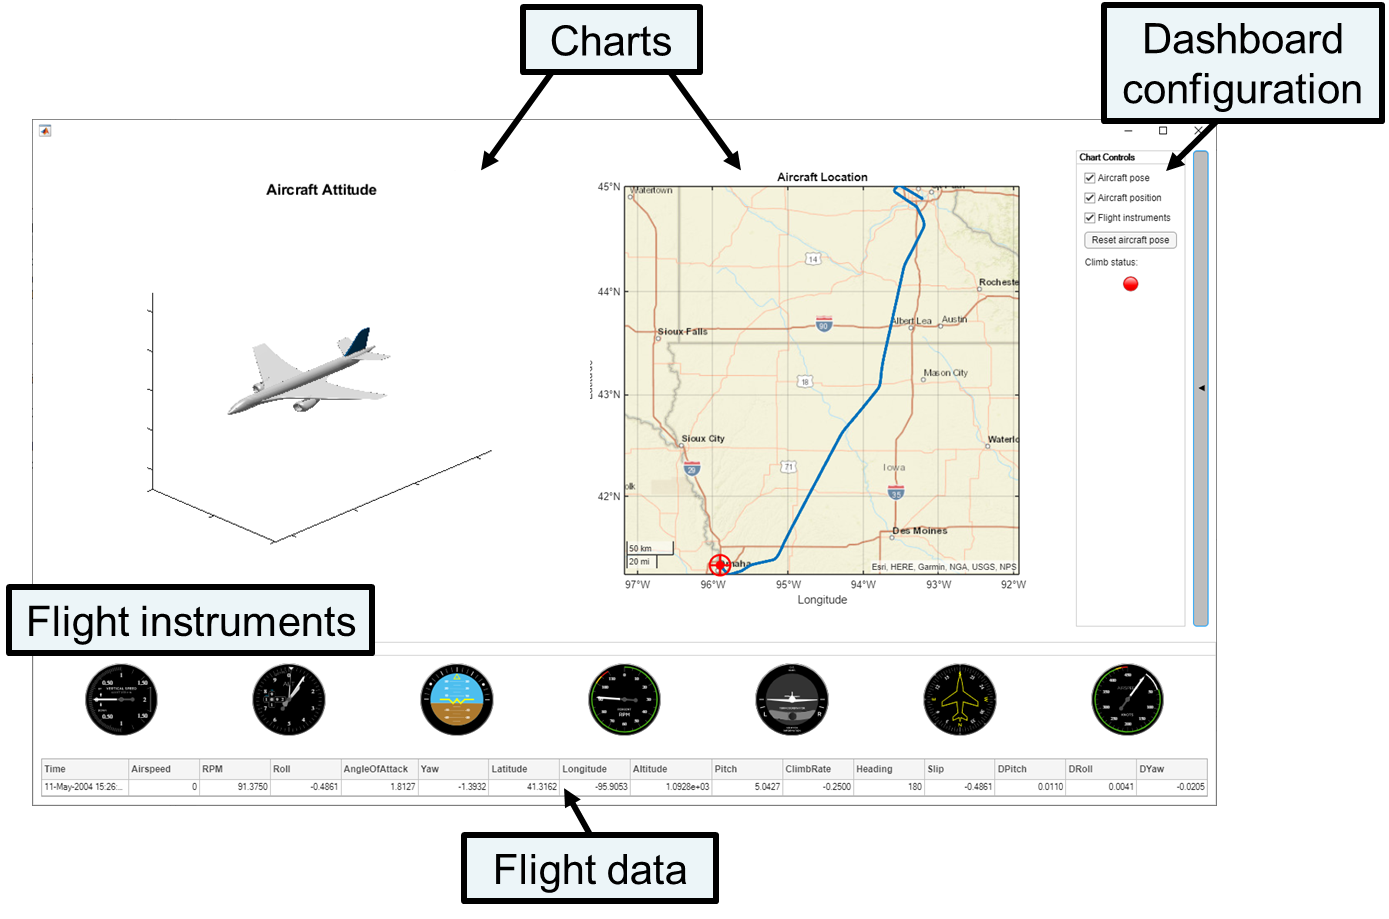

In this first blog post, we'll focus on creating an important part of the dashboard - a visualization to display a model of the aircraft together with its current attitude (roll, pitch, and yaw). We'll learn some general visualization techniques such as working with stereolithography (STL) files, 3D surfaces, and transforming 3D graphics.

In the next post in this series, we'll see how to encapsulate the 3D graphics and helper functions in a custom aircraft chart. This approach is more suited to modular application development. In the third and final post, we'll see how to connect the aircraft chart with other controls and displays in the final dashboard.

Let's get started!

## Import and visualize a 3D aircraft model.

We need a 3D aircraft model for our dashboard, so let's download one. We'll download a generic airplane design by Yorchmur on `printables.com` [1]. It's common for 3D models to be saved in [**STL**](https://en.wikipedia.org/wiki/STL_(file_format)) (stereolithography) files. These contain a surface triangulation (vertices, edges and faces) in a structured format. MATLAB provides the [`stlread`](matlab: doc stlread) function for importing data from STL files. 

The output of this function is a [`triangulation`](https://mathworks.com/help/matlab/ref/triangulation.html), containing vertices, edges, and faces. A triangulation is an efficient way to represent a large or complex surface. The `Points` property of the triangulation stores the vertices. The `ConnectivityList` property specifies how the vertices are connected within the triangulation - each row of this matrix represents a triangle.

url = "https://files.printables.com/media/prints/34767/stls/343468_b085a064-c28f-4861-b1a0-6a559929a7e2/avion31.stl";
opts = weboptions("ContentReader", @stlread);
tr = webread(url, opts);
disp(tr)

It's easy to visualize the 3D surface defined by this triangulation. Triangulations have several dedicated visualization functions, including [`trisurf`](https://mathworks.com/help/matlab/ref/trisurf.html), [`trimesh`](https://www.mathworks.com/help/matlab/ref/trimesh.html), and [`triplot`](https://www.mathworks.com/help/matlab/ref/triplot.html). We'll use `trisurf` to render our aircraft using a smooth surface plot. In fact, [`trisurf`](https://mathworks.com/help/matlab/ref/trisurf.html) creates a [`patch`](https://mathworks.com/help/matlab/ref/patch.html) for optimal performance.

figure
trisurf(tr)

## Improve the default 3D visualization of the aircraft.

We can see an aircraft-shaped blob in our axes, but this visualization won't win any prizes. Let's improve our aircraft visualization by customizing some `axes` and `patch` properties. These objects are highly customizable - see [**Axes Properties**](https://www.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html) and [**Patch Properties**](https://www.mathworks.com/help/matlab/ref/matlab.graphics.primitive.patch-properties.html) for further details.

We'll paint the aircraft, add lighting to the scene from directly above, and make the aircraft skin extra shiny using the [`material`](https://mathworks.com/help/matlab/ref/material.html) function.

The lighting properties for `patch` and `surface` objects are only activated when there is a [`light`](matlab: doc light) object in the axes. See [**Lighting Overview**](https://www.mathworks.com/help/matlab/creating_plots/lighting-overview.html) for further details. 

First, we'll create a two-color scheme for painting the aircraft, using gray and blue. The colormap will have 500 points, comprising 250 gray and 250 blue points. This means that any point on the aircraft with $z$-coordinate below 500 will be colored gray, whereas any point with $z$-coordinate above 250 will be blue. The choice of 250 corresponds to the $z$-coordinate of the base of the aircraft's tail.

blue = [0, 0.447, 0.741];
gray = 0.95 * ones(1, 3);
onesMatrix = ones(250, 3);
paintJob = [gray .* onesMatrix; blue .* onesMatrix];

Here, the units are arbitrary and could be rescaled if needed.

x = [-2000, 2000];
y = [-2500, 4500];
z = [-2500, 2500];

Create the `figure` and `axes`.

f = figure;
ax = axes("Parent", f, ...    
    "Colormap", paintJob, ...    
    "View", [225, 25], ...
    "DataAspectRatio", [1, 1, 1], ...
    "XLim", x, ...
    "YLim", y, ...
    "ZLim", z, ...
    "XTickLabel", [], ...
    "YTickLabel", [], ...
    "ZTickLabel", [], ...    
    "NextPlot", "add");
aircraft = trisurf(tr, "Parent", ax, ...
    "FaceAlpha", 0.9, ...
    "FaceColor", "interp", ...
    "EdgeAlpha", 0, ...
    "FaceLighting", "gouraud");
title("Aircraft Attitude")
light(ax, "Position", [0, 0, 1])
material(ax, "shiny")

## Prepare the aircraft for geometric transformation.

Great, now we have a visualization of the aircraft that looks reasonable. However, the aircraft has a fixed attitude, with zero pitch, roll, and yaw. To visualize the changing attitude of the aircraft during a flight, we need the ability to set the pitch, roll, and yaw angles to any value.

We'll approach this task using a *transform.* In this context, a *transform* is a geometric operation such as a rotation, scaling, or translation applied to a graphics object within a 3D axes. 

MATLAB provides the [`hgtransform`](https://www.mathworks.com/help/matlab/ref/hgtransform.html) function to create transform objects. The idea is that the transform is a container in which we can place any number of 3D graphics objects. When we apply a geometric transformation on this container, it takes care of moving all its constituent graphics objects.

Rather than perform the calculations needed to update the coordinates of each graphics object when we want to apply a transform, we instead manipulate the `Matrix` property of the transform. This is a 4-by-4 matrix representing the required transform, with default value equal to the 4-by-4 identity matrix, representing the null transform.

For further details on how this matrix is used to transform objects in 3D coordinate systems, see Cleve's excellent blog posts ([[2]](https://blogs.mathworks.com/cleve/2023/02/04/matrices-in-action-grafix-2-0/) and [[3]](https://blogs.mathworks.com/cleve/2023/02/10/grafix-users-guide/)) describing his interactive `Grafix` tool.

Let's create a new transform in the axes, and place our aircraft inside.

tf = hgtransform("Parent", ax);
aircraft.Parent = tf;

## Adjust the aircraft's attitude using the transform.

We're now ready to adjust the aircraft's attitude. We'll use the three functions `roll`, `pitch`, and `yaw` defined below to do this. For example, here is the code listing for the `roll` function, which in turn relies on the `rotate` helper function.

The `roll` function accepts the aircraft triangulation and an angle (specified in degrees). These values are passed onto the `rotate` function, together with the string `"y"`, representing a rotation around the $y$-axis. The `rotate` function then converts the angle from degrees to radians (using [`deg2rad`](https://www.mathworks.com/help/matlab/ref/deg2rad.html)) for compatibility with [`makehgtform`](https://www.mathworks.com/help/matlab/ref/makehgtform.html). This is a convenience function for creating the required 4-by-4 transformation matrix for a broad range of common operations, including the rotations we need to implement attitude adjustments to the aircraft. The `pitch` and `yaw` functions are implemented in a similar way.

As an example, the following code creates the transformation matrix representing a rotation of 15 degrees about the z-axis. This corresponds to changing the aircraft's yaw.

yawAdjustment = makehgtform("zrotate", deg2rad(15));
disp("Transformation matrix for a 15 degree rotation about the z-axis:")
disp(yawAdjustment)

Next, apply this transformation to our aircraft. Note that if we want to apply a sequence of transformations represented by the matrices $T_1, T_2, \dots, T_n$ to our aircraft, we multiply the transformation matrices on the right ($T_1T_2\cdots T_n$) to accumulate the changes. This property of transformation matrices makes it easy to adjust the aircraft's attitude thoughout the flight.

tf.Matrix = tf.Matrix * yawAdjustment;

Finally, we'll use the `roll` function to create an animation of our aircraft performing a loop.

for k = 1:72
    roll(aircraft, 5)
    pause(0.05)
end

## Summary

We've seen how to import STL model data into MATLAB and create a customized visualization of the corresponding 3D surface. We also introduced the concept of transforms, and how to use these to move 3D graphics objects around in a convenient way.

In the next post, we'll see how to encapsulate the 3D graphics and `roll`, `pitch`, and `yaw` functions in a custom aircraft chart. This approach is more suited to modular application development, and enables us to share the visualization with colleagues or embed it in a larger application.

## Roll, pitch, and yaw functions.

function roll(aircraft, theta)

rotate(aircraft, theta, "y")

end

function pitch(aircraft, theta)

rotate(aircraft, theta, "x")

end

function yaw(aircraft, theta)

rotate(aircraft, theta, "z")

end

function rotate(aircraft, theta, rotationAxis)

arguments ( Input )
    aircraft(1, 1) matlab.graphics.primitive.Patch
    theta(1, 1) double {mustBeReal, mustBeFinite}
    rotationAxis(1, 1) string {mustBeMember(rotationAxis, ["x", "y", "z"])}
end

theta = deg2rad(theta);
tf = aircraft.Parent;
tf.Matrix = tf.Matrix * makehgtform(rotationAxis + "rotate", theta);

end

## References

- [1] *Airplane* by Yorchmur, [`https://www.printables.com/model/34767-airplane`,](https://www.printables.com/model/34767-airplane,) accessed in November 2023, licensed under the Creative Commons Attribution 4.0 International License.

- [2] *Matrices in Action, Grafix 2.0*, by Cleve Moler, [`https://blogs.mathworks.com/cleve/2023/02/04/matrices-in-action-grafix-2-0/`](https://blogs.mathworks.com/cleve/2023/02/04/matrices-in-action-grafix-2-0/)

- [3] Grafix Users' Guide, by Cleve Moler, [`https://blogs.mathworks.com/cleve/2023/02/10/grafix-users-guide/`](https://blogs.mathworks.com/cleve/2023/02/10/grafix-users-guide/) 